# Diseño LQR

Q = [100000, 0; 0, 1000]; 
R = 1.4; 

[K, ARE_s, CL_p] = lqr(Gss, Q, R); 
CL_p

CL_p =   -12.5537
  -21.0471


A_lqr = (A - B*K); 
B_lqr =  1/0.0037 * B; 
C_lqr = C; 
D_lqr = 0; 

Gcl = ss(A_lqr, B_lqr, C_lqr, D_lqr); 
damp(Gcl)

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
 -1.26e+01     1.00e+00       1.26e+01         7.97e-02    
 -2.10e+01     1.00e+00       2.10e+01         4.75e-02    


dcgain(Gcl)

ans = 0.9968

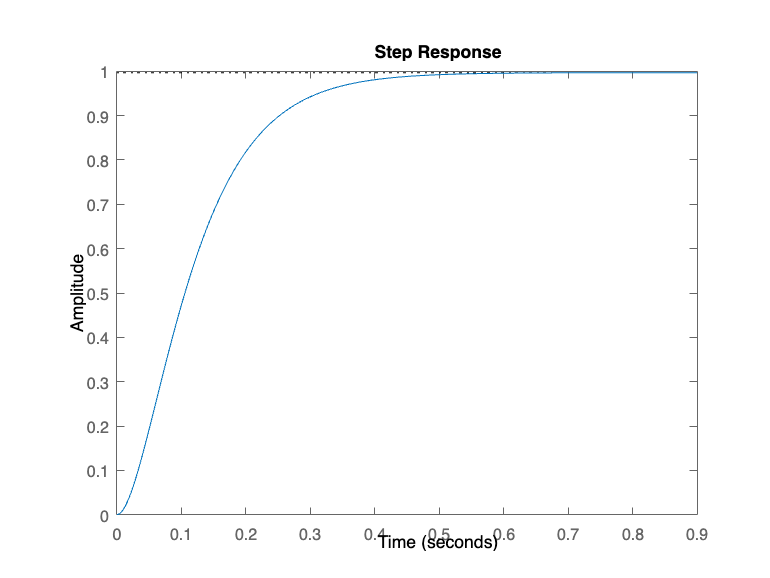

step(Gcl)

## implementacion

discreteLQR = c2d(, 2.5e-3, 'tustin'); 

Error using c2d
The A matrix must be square.